clear; close all; clc;
dt1 =2; At1 = pi*dt1^2/4;
A01 =0.0209;
dt2=2; At2 = pi*dt2^2/4;
A02 =0.0231;
Kp = 0.025;  b = Kp/At2;
g = 9.8;
a2 = (A02*sqrt(2*g)) / At2;   a1 = (A01*sqrt(2*g)) / At1;

%% =========================================
% 0) ACCESO A DATOS DE SIMULINK
% =========================================
model_name = 'simulinkmodel'; 

try
    disp(['Iniciando simulación del modelo: ', model_name]);
    out = sim(model_name, 'SrcWorkspace', 'current'); 
    disp('Simulación completada con éxito. Variables creadas en "out".');
catch ME
    error('ERROR CRÍTICO: No se pudo ejecutar el modelo de Simulink. Asegúrese de que el archivo .slx y este script estén en la misma carpeta.');
end

Iniciando simulación del modelo: simulinkmodel


Simulación completada con éxito. Variables creadas en "out".



try
    t_simulink  = out.tout;
    L1_simulink = out.yout.signals(1).values; 
    L2_simulink = out.yout1.signals(1).values; 
    disp('✅ Datos de Simulink (yout, yout1) cargados correctamente.');
catch ME
    try
        t_simulink = out.yout.time; 
        L1_simulink = out.yout.data;
        L2_simulink = out.yout1.data; 
        disp('✅ Datos de Simulink cargados en formato Timeseries.');
    catch
        error('ERROR: El formato de los bloques To Workspace (yout/yout1) no es compatible.');
    end
end

✅ Datos de Simulink (yout, yout1) cargados correctamente.



%% =========================================
% 1) LECTURA Y PREPARACIÓN DE DATOS CSV
% =========================================
fileName = 'factorymodel.csv';   

fid = fopen(fileName,'r');
if fid == -1
    error('ERROR: Archivo CSV no encontrado. Verifique la ruta.');
end

raw = textscan(fid,'%s','Delimiter','\n');
fclose(fid);
raw = raw{1};

for i = 1:length(raw)
    raw{i} = strrep(raw{i}, ',', '.'); 
end

tmpFile = 'tmp_fixed.csv';
fid = fopen(tmpFile,'w');
for i = 1:length(raw)
    fprintf(fid,'%s\n',raw{i});
end
fclose(fid);

T = readtable(tmpFile,'Delimiter',';'); 


t_ms   = T{:,2};
L1_exp = T{:,5};
L2_exp = T{:,4}; 
u_exp  = T{:,3};

% 🚨 COMPENSACIÓN CLAVE: RETRASO DE 4 SEGUNDOS 🚨
t_real = (t_ms - t_ms(1))/1000 - 3;   % tiempo real [s]


%% =========================================
% 2) AJUSTE DE TIEMPO UNIFORME E INTERPOLACIÓN
% =========================================
dt = mean(abs(diff(t_real)));              
t = (0:length(t_real)-1)' * dt;      

L1_exp = interp1(t_real, L1_exp, t, 'linear', 'extrap');
L2_exp = interp1(t_real, L2_exp, t, 'linear', 'extrap');
u_exp  = interp1(t_real, u_exp , t, 'linear', 'extrap');

L1_simulink = interp1(t_simulink, L1_simulink, t, 'linear', 'extrap');
L2_simulink = interp1(t_simulink, L2_simulink, t, 'linear', 'extrap');


%% =========================================
% 3) CÁLCULOS Y SIMULACIÓN LINEALIZADA Y PARÁMETROS DINÁMICOS
% =========================================
dt1 = 2; 
dt2 = 2;
At1 = pi*dt1^2/4;
At2 = pi*dt2^2/4; 
A01 = 0.0208; 
A02 = 0.023;  
Kp = 0.025; 
g  = 9.8;
a2 = (A02*sqrt(2*g)) / At1;
a1 = (A01*sqrt(2*g)) / At1;
b  = Kp/At2;

vp = mean(u_exp); 
l2_eq = ((b*vp)/a2)^2; 
l1_eq = ((a2*sqrt(l2_eq))/a1)^2;
x1e = l1_eq;
x2e = l2_eq;
fprintf('L1_eq = %.4f m\n', x1e); fprintf('L2_eq = %.4f m\n', x2e);

L1_eq = 1.8426 m
L2_eq = 1.5070 m



s1 = sqrt(x1e); s2 = sqrt(x2e);
A = [ -a1/(2*s1),  a2/(2*s2); 0 , -a2/(2*s2) ]; B = [0; b]; C = eye(2); D = [0;0]; sys = ss(A,B,C,D);
u_dev = u_exp - vp; x0_dev = [L1_exp(1) - x1e; L2_exp(1) - x2e];
[y_dev, ~] = lsim(sys, u_dev, t, x0_dev);
L1_lin = x1e + y_dev(:,1); 
L2_lin = x2e + y_dev(:,2);

% --- CÁLCULO DE TAU Y TS ---
sys_tf = tf(sys);
polos_sistema = pole(sys);
tau_valores = -1 ./ polos_sistema; 
tau1 = max(tau_valores); 
tau2 = min(tau_valores); 
Ts1 = 4 * tau1; 
Ts2 = 4 * tau2; 


%% =========================================
% 4) FILTRADO DE DATOS Y DETERMINACIÓN DE L_FINAL
% =========================================
t_end = t(end) - 4; 
idx = t <= t_end; 
t_f = t(idx); 

L1_exp_f = L1_exp(idx); L2_exp_f = L2_exp(idx); 
L1_lin_f = L1_lin(idx); L2_lin_f = L2_lin(idx); 
L1_sim_f = L1_simulink(idx); L2_sim_f = L2_simulink(idx);

[~, idx_Ts] = min(abs(t_f - Ts1)); 
L1_final_Ts = L1_lin_f(idx_Ts);
L2_final_Ts = L2_lin_f(idx_Ts);


%% =========================================
% 5) CÁLCULO DE MÉTRICAS DE VALIDACIÓN CUANTITATIVA
% =========================================
calculate_metrics = @(L_real, L_model) struct(...
    'RMSE', sqrt(mean((L_real - L_model).^2)), ...
    'R2', 1 - (sum((L_real - L_model).^2) / sum((L_real - mean(L_real)).^2)) ...
);

metrics_sim_L1 = calculate_metrics(L1_exp_f, L1_sim_f);
metrics_sim_L2 = calculate_metrics(L2_exp_f, L2_sim_f); 
metrics_lin_L1 = calculate_metrics(L1_exp_f, L1_lin_f);
metrics_lin_L2 = calculate_metrics(L2_exp_f, L2_lin_f); 

disp(' ');

disp('====================================================');

disp('  TABLA DE VALIDACIÓN CUANTITATIVA (RMSE y R^2)');

  TABLA DE VALIDACIÓN CUANTITATIVA (RMSE y R^2)


disp('====================================================');

disp('MODELO SIMULINK (NO LINEAL)');

MODELO SIMULINK (NO LINEAL)


disp(['  L1 | RMSE: ', num2str(metrics_sim_L1.RMSE, '%.4f'), ' | R^2: ', num2str(metrics_sim_L1.R2, '%.4f')]);

  L1 | RMSE: 0.2731 | R^2: -0.0571


disp(['  L2 | RMSE: ', num2str(metrics_sim_L2.RMSE, '%.4f'), ' | R^2: ', num2str(metrics_sim_L2.R2, '%.4f')]);

  L2 | RMSE: 0.2836 | R^2: 0.6394


disp('----------------------------------------------------');

----------------------------------------------------


disp('MODELO LINEALIZADO');

MODELO LINEALIZADO


disp(['  L1 | RMSE: ', num2str(metrics_lin_L1.RMSE, '%.4f'), ' | R^2: ', num2str(metrics_lin_L1.R2, '%.4f')]);

  L1 | RMSE: 0.3316 | R^2: -0.5580


disp(['  L2 | RMSE: ', num2str(metrics_lin_L2.RMSE, '%.4f'), ' | R^2: ', num2str(metrics_lin_L2.R2, '%.4f')]);

  L2 | RMSE: 0.2554 | R^2: 0.7074


disp('====================================================');

disp('PARÁMETROS DINÁMICOS CLAVE');

PARÁMETROS DINÁMICOS CLAVE


disp(['Polo 1 (Dominante): ', num2str(polos_sistema(1))]);

Polo 1 (Dominante): -0.010797


disp(['Polo 2: ', num2str(polos_sistema(2))]);

Polo 2: -0.013201


disp(['Constante de Tiempo tau_1: ', num2str(tau1, '%.4f'), ' segundos']);

Constante de Tiempo tau_1: 92.6205 segundos


disp(['Constante de Tiempo tau_2: ', num2str(tau2, '%.4f'), ' segundos']);

Constante de Tiempo tau_2: 75.7492 segundos


disp(['Tiempo de Asentamiento Dominante (Ts1 = 4*tau1): ', num2str(Ts1, '%.2f'), ' segundos']);

Tiempo de Asentamiento Dominante (Ts1 = 4*tau1): 370.48 segundos


disp(['Tiempo de Asentamiento Secundario (Ts2 = 4*tau2): ', num2str(Ts2, '%.2f'), ' segundos']);

Tiempo de Asentamiento Secundario (Ts2 = 4*tau2): 303.00 segundos


disp('----------------------------------------------------');

----------------------------------------------------


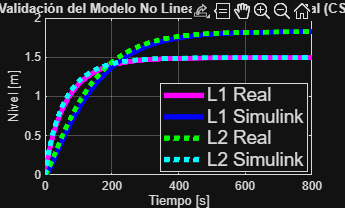



%% =========================================
% 6) GRÁFICA 1: SIMULINK (NO LINEAL) vs. REAL
% =========================================
figure('Name', 'Simulink vs Real'); 
plot(t_f, L1_exp_f, 'm', 'LineWidth', 4); hold on; 
plot(t_f, L2_exp_f, 'b', 'LineWidth', 4);  
plot(t_f, L1_sim_f, 'g:', 'LineWidth', 4);         
        
plot(t_f, L2_sim_f, 'c:', 'LineWidth', 4);         

grid on;
xlabel('Tiempo [s]');
ylabel('Nivel [m]');
title('Validación del Modelo No Lineal (Simulink) vs. Real (CSV)');

% Aquí agrandamos la leyenda con 'FontSize'
legend('L1 Real','L1 Simulink','L2 Real','L2 Simulink', ...
       'Location', 'best', 'FontSize', 14); 

% Límite de tiempo a 800 segundos
xlim([0 800]);

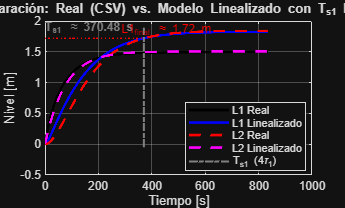


%% =========================================
% 7) GRÁFICA 2: LINEALIZADO vs. REAL (L1 y L2 JUNTAS)
% 🚨🚨 SE ELIMINARON LAS MARCAS DE L2_FINAL 🚨🚨
% =========================================
figure('Name', 'Linealizado vs Real'); 
plot(t_f, L1_exp_f, 'k', 'LineWidth', 2); hold on; 
plot(t_f, L2_exp_f, 'b', 'LineWidth', 2);     
plot(t_f, L1_lin_f, 'r--', 'LineWidth', 2);        
     
plot(t_f, L2_lin_f, 'm--', 'LineWidth', 2);        

% --- MARCAS DE TIEMPO DE ASENTAMIENTO (Ts1) ---
% 1. Linea Vertical en Ts1
plot([Ts1, Ts1], [min(L2_lin_f)-0.05, max(L1_lin_f)+0.05], 'Color', [0.5 0.5 0.5], 'LineStyle', '-.', 'LineWidth', 1.5, 'DisplayName', ['Ts = ', num2str(Ts1, '%.2f'), ' s']);
text(Ts1 * 0.9, max(L1_lin_f)+0.04, ['T_{s1} \approx ', num2str(Ts1, '%.2f'), ' s'], 'HorizontalAlignment', 'right', 'Color', [0.5 0.5 0.5], 'FontSize', 9, 'FontWeight', 'bold');

% 2. Línea Horizontal para Altura Final L1 (Termina en Ts1)
plot([0, Ts1], [L1_final_Ts, L1_final_Ts], 'r:', 'LineWidth', 1, 'HandleVisibility', 'off'); 

% 3. ---- SE ELIMINÓ LA LÍNEA HORIZONTAL DE L2 ----
% plot([0, Ts1], [L2_final_Ts, L2_final_Ts], 'm:', 'LineWidth', 1, 'HandleVisibility', 'off'); 

% 4. Texto de la Altura L1
text(Ts1 * 0.7, L1_final_Ts, [' L1_{final} \approx ', num2str(L1_final_Ts, '%.2f'), ' m'], ...
    'HorizontalAlignment', 'left', 'VerticalAlignment', 'bottom', 'Color', 'r', 'FontSize', 9);

% 5. ---- SE ELIMINÓ EL TEXTO DE L2 ----
% text(Ts1 * 0.7, L2_final_Ts, [' L2_{final} \approx ', num2str(L2_final_Ts, '%.2f'), ' m'], ...
%    'HorizontalAlignment', 'left', 'VerticalAlignment', 'top', 'Color', 'm', 'FontSize', 9);

grid on;
xlabel('Tiempo [s]');
ylabel('Nivel [m]');
title(['Comparación: Real (CSV) vs. Modelo Linealizado con T_{s1} Marcado']);
legend('L1 Real','L1 Linealizado','L2 Real','L2 Linealizado','T_{s1} (4\tau_1)','Location','best');